path = "D:\Whale Data\AcousticTrends_BlueFinLibrary\casey2017\wav\";
%FILE 20170521_000000 CASEY2017
fname = "20170521_000000.wav";
[x, fs] = audioread(path + fname);

numel(x)/2^18

ans = 13.7324

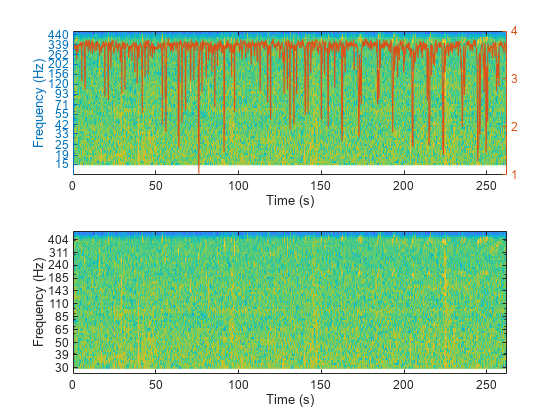

L = 2^18;
startidx = 5;
y = x(startidx*L + 1 : startidx*L + L);
fb = SFB(16, 0.05, fs, L, 30, 500);
s = fb.filterS(y);
fb.plotS(s.^2, true);

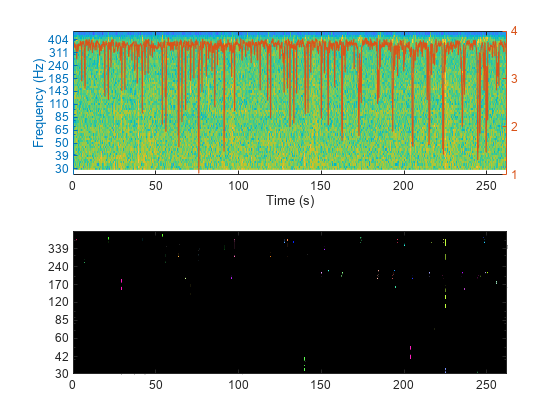

c = Contours(fb, s.^2);
c.fitGMM(true);
c.extractContours();
c.debugplot(fb);

path = "D:\Whale Data\AcousticTrends_BlueFinLibrary\BallenyIslands2015\";
files = dir(path)

files = 20×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


annotations = convertCharsToStrings({files.name})

annotations = 1×20 string array
    "."    ".."    "Balleny2015.BmAnt-A.selections.txt"    "Balleny2015.BmAnt-B.selections.txt"    "Balleny2015.BmAnt-Z.selections.txt"    "Balleny2015.BmD.selections.txt"    "Balleny2015.Bp20Hz.selections.txt"    "Balleny2015.Bp20Plus.selections.txt"    "Balleny2015.BpDwnswp.selections.txt"    "Balleny2015.BpHigherCall.selections.txt"    "Balleny2015.humpback.selections.txt"    "Balleny2015.minke.selections.txt"    "Balleny2015.unid.selections.txt"    "BallenyIs2015_IWC_Annotation_FinalReport.docx"    "SORP Annotated Library - BallenyIslands2015.wsp"    "annotation_metadata_Baleeny2015_HC03_FINAL.xlsx"    "ballenyIslands2015_spectrogramCorrelation_abwz_allAnnotations.sqlite3"    "roc_energyDetector_Bp20_ballenyIslands2015.sqlite3"    "wav"    "~$llenyIs2015_IWC_Annotation_FinalReport.docx"


idx = arrayfun(@(s) s.contains("selections.txt"), annotations)

idx = 1×20 logical array
   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0


annotations = annotations(idx)

annotations = 1×11 string array
    "Balleny2015.BmAnt-A.selections.txt"    "Balleny2015.BmAnt-B.selections.txt"    "Balleny2015.BmAnt-Z.selections.txt"    "Balleny2015.BmD.selections.txt"    "Balleny2015.Bp20Hz.selections.txt"    "Balleny2015.Bp20Plus.selections.txt"    "Balleny2015.BpDwnswp.selections.txt"    "Balleny2015.BpHigherCall.selections.txt"    "Balleny2015.humpback.selections.txt"    "Balleny2015.minke.selections.txt"    "Balleny2015.unid.selections.txt"


ann = {}


ann =

  0×0 empty cell array



for fname = annotations
    T = readtable(path + fname, "Delimiter","\t");
    idx = find(fname{:} == '.')
    type = extractBetween(fname, idx(1)+1, idx(end-1)-1);
    type = type.replace(".", "_");
    type = repmat(type, size(T, 1), 1);
    T(:, 'Type') = cellstr(type);
    ann{end + 1} = T;
end

idx =     12    20    31


idx =     12    20    31


idx =     12    20    31


idx =     12    16    27


idx =     12    19    30


idx =     12    21    32


idx =     12    21    32


idx =     12    25    36


idx =     12    21    32


idx =     12    18    29


idx =     12    17    28


masterTable = {};
for T = ann
    T = T{:};
    t = table();
    t.File = convertCharsToStrings(T.BeginFile);
    t.StartIdx = T.BegFileSamp_samples_;
    t.EndIdx = T.EndFileSamp_samples_;
    t.Duration = T.DeltaTime_s_;
    t.StartFrequency = T.LowFreq_Hz_;
    t.EndFrequency = T.HighFreq_Hz_;
    t.Annotation = convertCharsToStrings(T.Type);
    masterTable{end + 1} = t;
end
masterTable = vertcat(masterTable{:});
masterTableBlueFin = masterTable(masterTable.Annotation ~= "Unidentified_calls" & masterTable.Annotation ~= "unid", :);
minF = min(masterTableBlueFin.StartFrequency)

minF = 8.1000

maxF = max(masterTableBlueFin.EndFrequency)

maxF = 484.4000